clear

#### Read MFD data

[B0,freqs1,defects] = readMFD('data/B_defectless.txt');
assert(isempty(defects))

[B ,freqs2,defects] = readMFD('data/B_defect_circ8mm.txt');
assert(all(freqs1==freqs2))

freqs = freqs1;
delta_B = B - B0;

% currently use only one frequency
freqs = freqs(3);
delta_B = delta_B(3,:).';

clear freqs1 freqs2 B0 B

#### Load sensitivity matrix

load(sprintf('data/Sensitivity_%dHz.mat', freqs))

global xylim
xylim = 20e-3;
mask = -xylim < element_centers(1,:) &  element_centers(1,:) < xylim & ...
       -xylim < element_centers(2,:) &  element_centers(2,:) < xylim & element_centers(3,:) > -1.5e-3;

S = S(:, mask);
element_centers = element_centers(:, mask);

clear xylim mask 

#### Reconstruction

Psi = groupBlock(element_centers, 5,5,1);
Phi = S * Psi;
y = delta_B;

h = 25;
g = size(Phi,2) / h;
M = length(delta_B);

mu_x = zeros(g*h, 1);
Sigma_x = sparse(g*h, g*h);

gamma = ones(1,1,g);

lambda = 0.01 * sqrt( norm(y-mean(y)).^2 / (length(y)-1) );
B = autoRegressiveCorrelation(0.9, h);

for iter = 1:3
    Sigma_0 = blockDiag(gamma .* B);
    Sigma_y = lambda * eye(size(Phi,1)) + Phi * Sigma_0 * Phi';
    Sigma_y = decomposition(Sigma_y);

    temp = Phi * Sigma_0;
    Sigma_x = Sigma_0 - temp' * (Sigma_y \ temp);
    mu_x = Sigma_0 * Phi' * (Sigma_y \ y);

    tr = 0;
    B_temp = zeros(size(B));
    for i = 1:g
        rows = h * (i-1) + 1 : h * i;
        Sigma_x_i = Sigma_x(rows,rows);
        mu_x_i = mu_x(rows);

        gamma(i) = trace(B \ (Sigma_x_i + mu_x_i * mu_x_i')) / h;
%         gamma(i) = real(gamma(i));

        Phi_i = Phi(:,rows);
        tr = tr + trace(Sigma_x_i * (Phi_i' * Phi_i));

        B_temp = B_temp + (Sigma_x_i + mu_x_i * mu_x_i') / g / gamma(i);
    end
    tr = real(tr);

    lambda = (norm(y - Phi * mu_x)^2 + tr) / M;

    r = mean(diag(B_temp,1)) / mean(diag(B_temp));
    r = sign(r) * min(abs(r), 0.99);
    B = autoRegressiveCorrelation(r, h);
end

tr = 0

tr = 0

tr = 0

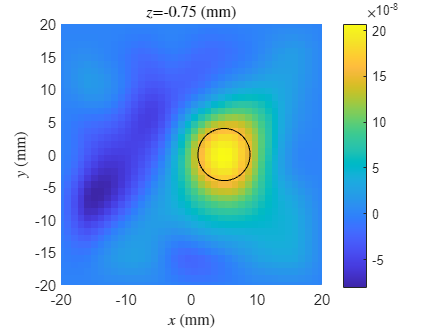

delta_sigma = Psi * mu_x;

displayReconstruction(delta_sigma, element_centers, defects)

function Psi = groupBlock(element_centers, bx,by,bz)

n = size(element_centers,2);
nx = length(unique(element_centers(1,:)));
ny = length(unique(element_centers(2,:)));
nz = length(unique(element_centers(3,:)));

x   = reshape(element_centers(1,:), nx,ny,nz);
y   = reshape(element_centers(2,:), nx,ny,nz);
z   = reshape(element_centers(3,:), nx,ny,nz);
idx = reshape(1:n, nx,ny,nz);

assert(all(x == x(:,1,1), 'all'));
assert(all(y == y(1,:,1), 'all'));
assert(all(z == z(1,1,:), 'all'));

Psi = sparse(size(element_centers,2), 0);

p = 0;
for i = 1:nx-bx+1
for j = 1:ny-by+1
for k = 1:nz-bz+1
    for l = 1:bx
    for m = 1:by
    for n = 1:bz
        p = p + 1;
        elem = idx(i+l-1, j+m-1, k+n-1);
        Psi(elem,p) = 1;
    end
    end
    end
end
end
end

end

function B = autoRegressiveCorrelation(r, h)
v = ones(1,h);
for i = 2:h
    v(i) = v(i-1) * r;
end
B = toeplitz(v);
end

function B = blockDiag(As)
B = sparse(size(As,1)*size(As,3), size(As,2)*size(As,3));
for k = 1:size(As,3)
    rows = size(As,1) * (k-1) + 1 : size(As,1) * k;
    cols = size(As,2) * (k-1) + 1 : size(As,2) * k;
    B(rows,cols) = As(:,:,k);
end
end

function [B, freqs, defects] = readMFD(fname)

B = [];
freqs = [];
defects = {};

lines = readlines(fname);

for k = 1:length(lines)
    str = strtrim(lines(k));
    str = convertStringsToChars(str);
    if isempty(str)
        continue
    end

    if ~startsWith(str, '%')
        B(end+1,:) = str2num(str);
    else
        str = strtrim(str(2:end));
        if startsWith(str, 'frequency')
            tokens = split(str);
            freqs(end+1) = str2num(tokens{2});
            assert(strcmp(tokens{3}, "Hz"))
        elseif startsWith(str, 'defect')
            i = strfind(str, ' ');
            defects{end+1} = jsondecode(str(i:end));
        else
            error('Unknown "%s"', str)
        end
    end
end

end

function displayReconstruction(delta_sigma, element_centers, defects)

c = real(-delta_sigma);

z = unique(element_centers(3,:));
z = sort(z, 'descend');

scale = 1e3;

global xylim
lim = [-xylim xylim] * scale;

figure('Position',[10 10 400 300*length(z)])
for k = 1:length(z)
    mask = element_centers(3,:) == z(k);
    c_layer = reshape(c(mask), sqrt(sum(mask)),[]);

    subplot(length(z),1,k)
    hold on
    imagesc(lim,lim, c_layer.', [min(c) max(c)])
    colorbar
    axis square xy
    box on
    xlim(lim)
    ylim(lim)
    title(sprintf('$z$=%g (mm)',z(k)*scale), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')

    for p = 1:length(defects)
        defect = defects{p};
        if ~(min(defect.z1, defect.z2) <= z(k) && z(k) <= max(defect.z1, defect.z2))
            continue
        end
        switch lower(defect.type)
            case 'rectangular'
                rect = [defect.c_x-defect.dx/2 defect.c_y-defect.dy/2 defect.dx defect.dy];
                rectangle('Position', rect * scale)
            case 'circular'
                theta = linspace(0, 2*pi);
                x = defect.c_x + defect.d/2 * cos(theta);
                y = defect.c_y + defect.d/2 * sin(theta);
                plot(x * scale, y * scale, 'k')
            case 'polygonal'
                plot(defect.xs * scale, defect.ys * scale, 'k')
            otherwise
                error('Unknown defect shape "%s"', defect.type)
        end
    end
end

end